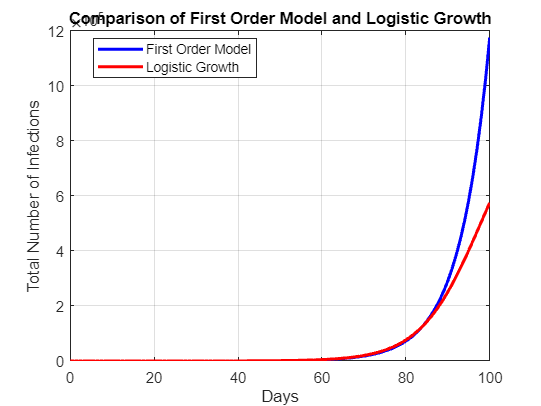

% Parameters
R0 = 1.15;
K = 1e6;
n_days = 100;

% Create a range for n
n = 0:n_days;

% Logistic growth function
logistic_growth = @(n) K ./ (1 + ((K * (R0 - 1) - R0) / (R0 - 1)) * R0.^-(n+1));

% First-order model
first_order_model = R0.^n;

% Plotting
figure;
plot(n, first_order_model, 'b', 'LineWidth', 2, 'DisplayName', 'First Order Model');
hold on;
plot(n, logistic_growth(n), 'r', 'LineWidth', 2, 'DisplayName', 'Logistic Growth');
title('Comparison of First Order Model and Logistic Growth');
xlabel('Days');
ylabel('Total Number of Infections');
legend('Location', 'best');
grid on;


% Find point of inflection using the first derivative
first_derivative = diff(logistic_growth(n));
inflection_point_first_derivative = find(first_derivative == max(first_derivative));

% Find point of inflection using the zero-crossing of the second derivative
second_derivative = diff(first_derivative);
inflection_point_second_derivative = find(second_derivative(1:end-1) .* second_derivative(2:end) <= 0);

% Display results
fprintf('Point of inflection using first derivative: Day %d\n', inflection_point_first_derivative);

Point of inflection using first derivative: Day 98


fprintf('Point of inflection using second derivative: Day %d\n', inflection_point_second_derivative);

Point of inflection using second derivative: Day 97


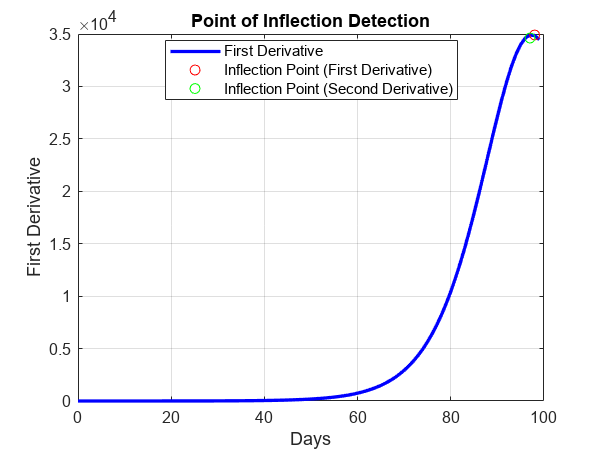


% Plotting the point of inflection
figure;
plot(n(1:end-1), first_derivative, 'b', 'LineWidth', 2, 'DisplayName', 'First Derivative');
hold on;
plot(inflection_point_first_derivative, first_derivative(inflection_point_first_derivative), 'ro', 'DisplayName', 'Inflection Point (First Derivative)');
plot(inflection_point_second_derivative, first_derivative(inflection_point_second_derivative), 'go', 'DisplayName', 'Inflection Point (Second Derivative)');
title('Point of Inflection Detection');
xlabel('Days');
ylabel('First Derivative');
legend('Location', 'best');
grid on;